## Оценка параметров реального китайского привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
% csv = readmatrix("csv/rchi_voltage_current_no_load.csv");
csv = readmatrix("csv/rchi_voltage_current_new_wire_no_load.csv");

data_length = length(csv(:,2))-1

data_length = 256

ticks = csv(2:data_length+1, 2);    % тики
w = csv(2:data_length+1, 3)*3.1415/180.0;    % рад/с
u = csv(2:data_length+1, 4)/256*6.0;  % шим
V = csv(2:data_length+1, 5);  % В
I = csv(2:data_length+1, 6);  % А

I_orig = I;

% dt_sum = 0;
% for k = 2:data_length
%     dt = time(k) - time(k-1);
%     dt_sum = dt_sum + dt;
%     dI_orig(k) = (current(k)-current(k-1))/dt;
% end

V = smooth(V, 100);
w = smooth(w, 10);
I = smooth(I, 10);

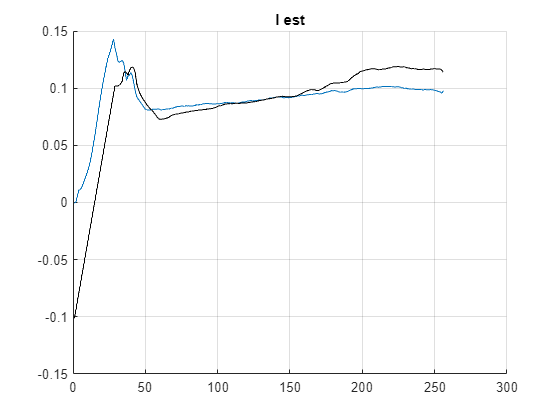

L = 0.0011;
R = 3.2298;
Kw = 0.2326;
Km = 0.1078;
J = 2.3865e-04;
Lam = 0.0010;

% M_ext_orig = J*dw_orig + Lam*w_sm - Km*current;
% I_est_orig = J*dw_orig/Km + Lam*w/Km;
% I_est_orig_u = (V - Kw*w)/R;
I_est_orig_u = (u-0.35 - Kw*w)/R;
% I_est = V/R - Kw/R*w_orig - J/Km*dw_orig;

figure;
hold on
plot(I)
% plot(time, I_est_orig)
plot(I_est_orig_u, "black")
% plot(I_est, "red")
hold off
title("I est")
xlim("auto")
ylim("auto")
grid on

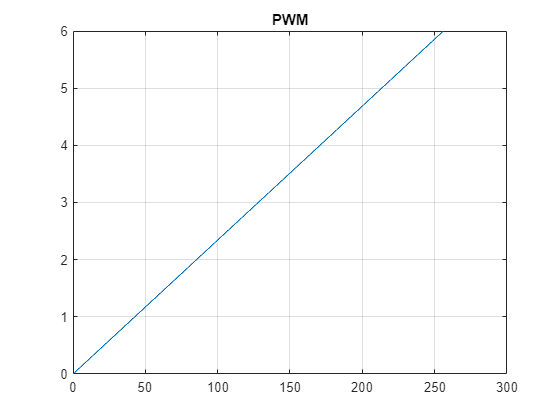

figure;
plot(u)
title("PWM")
xlim("auto")
ylim("auto")
grid on

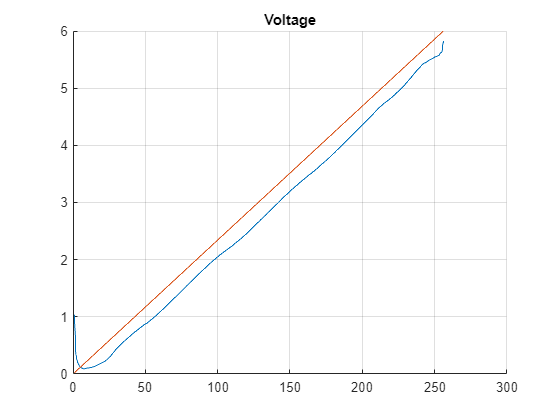


figure;
hold on
plot(V)
plot(u)
hold off
title("Voltage")
xlim("auto")
ylim("auto")
grid on


V_delta = V-u;
mean(V_delta(10:data_length))

ans = -0.3106

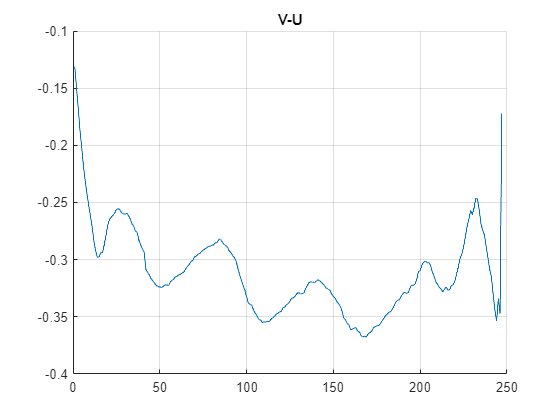


figure;
hold on
plot(V_delta(10:data_length))
hold off
title("V-U")
xlim("auto")
ylim("auto")
grid on

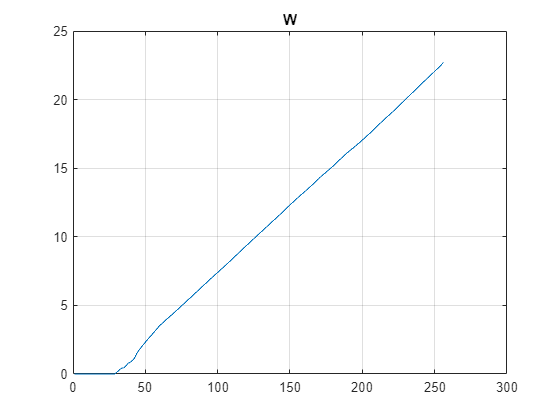


figure;
plot(w)
title("W")
xlim("auto")
ylim("auto")
grid on

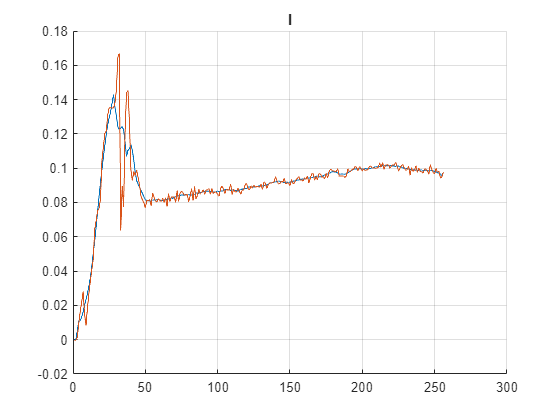


figure;
hold on
plot(I)
plot(I_orig)
hold off
title("I")
xlim("auto")
ylim("auto")
grid on

% R = 2.1053
R = 2.1902

R = 2.1902

Kw = (V-R.*I)./w;
Kw_avr = mean(Kw(60: data_length))

Kw_avr = 0.2451


Km = 0.19;
Lam = Km*I./w;
Lam_avr = mean(Lam(60: data_length))

Lam_avr = 0.0017

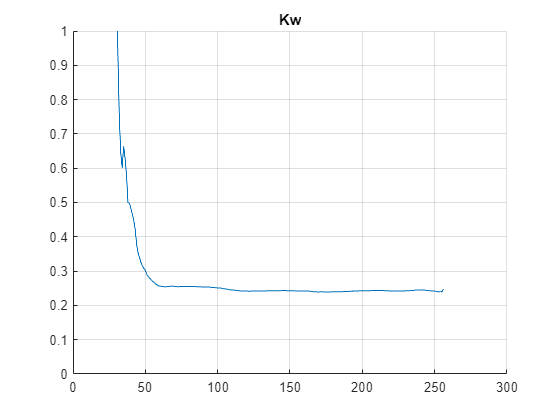


figure;
hold on
plot(Kw)
hold off
title("Kw")
xlim("auto")
% ylim("auto")
ylim([0 1])
grid on

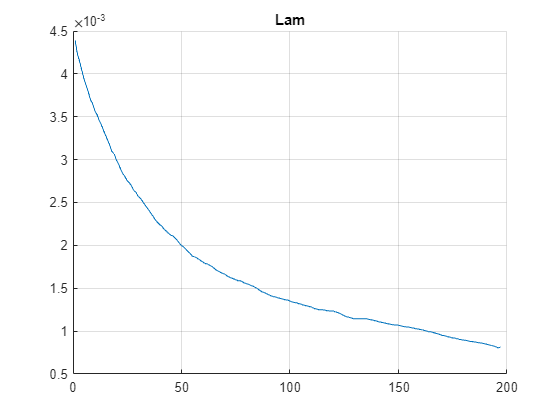


figure;
hold on
plot(Lam(60:data_length))
% plot(R_avr)
hold off
title("Lam")
xlim("auto")
ylim("auto")
grid on

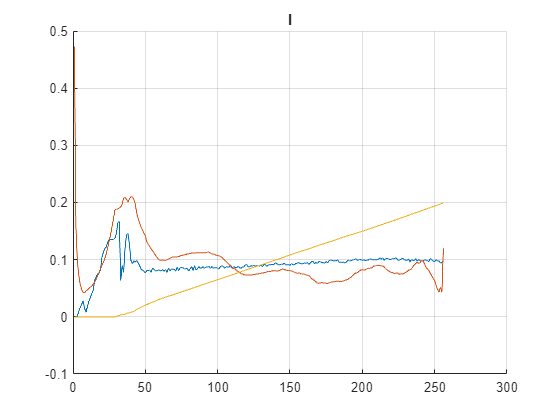


I_est = (V-Kw_avr*w)/R;
I_est1 = Lam_avr*w/Km;

figure;
hold on
plot(I_orig)
plot(I_est)
plot(I_est1)
hold off
title("I")
xlim("auto")
ylim("auto")
grid on

## Оценка параметров реального китайского привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
% csv = readmatrix("csv/rchi_voltage_current_load.csv");
csv = readmatrix("csv/rchi_voltage_current_new_wire_load.csv");

data_length = length(csv(:,2))-1-42

data_length = 214

ticks = csv(2:data_length+1, 2);    % тики
w = csv(2:data_length+1, 3);    % град/с
u = csv(2:data_length+1, 4);  % шим
V = csv(2:data_length+1, 5);  % В
I = csv(2:data_length+1, 6);  % А

% t_start = time(1);
% time = (time - t_start)/1000000;    % с
% tf = time(data_length)

% w_orig = smooth(w_orig, 5);
% dw_orig = smooth(dw_orig, 5);
% current = smooth(current, 5);

% dt_sum = 0;
% for k = 2:data_length
%     dt = time(k) - time(k-1);
%     dt_sum = dt_sum + dt;
%     dI_orig(k) = (current(k)-current(k-1))/dt;
% end

% dI_orig = smooth(dI_orig, 50);
% 
% dt = dt_sum/(data_length-1)

I_orig = I;

V = smooth(V, 50);
w = smooth(w, 10);
I = smooth(I, 10);

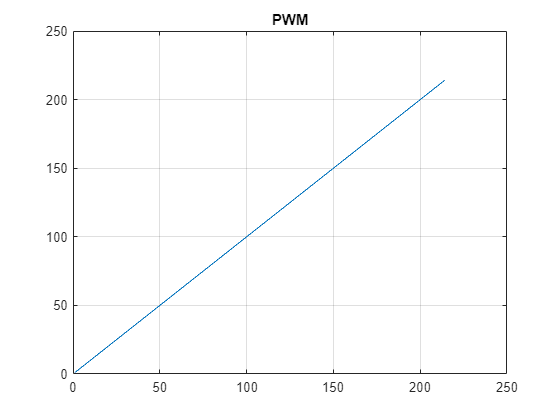

figure;
plot(u)
title("PWM")
xlim("auto")
ylim("auto")
grid on

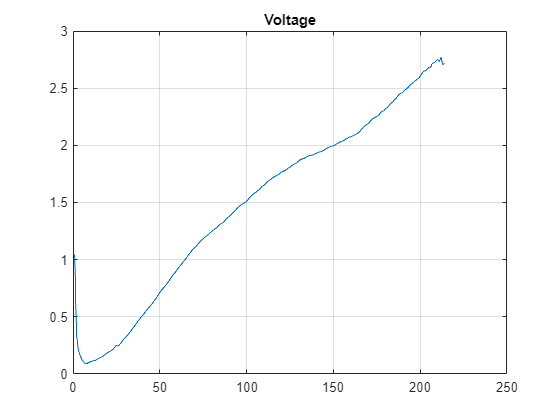


figure;
plot(V)
title("Voltage")
xlim("auto")
ylim("auto")
grid on

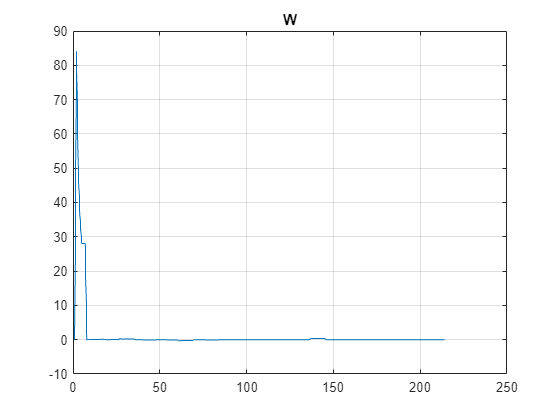


figure;
plot(w)
title("W")
xlim("auto")
ylim("auto")
grid on

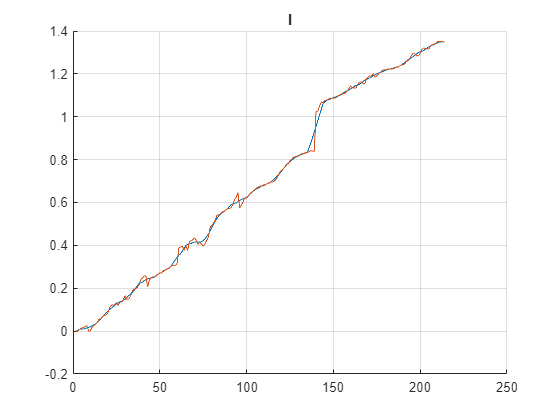


figure;
hold on
plot(I)
plot(I_orig)
hold off
title("I")
xlim("auto")
ylim("auto")
grid on


R = V./I;
% R_avr = mean(R(2:data_length))
R_avr = mean(R(60:data_length))

R_avr = 2.1902

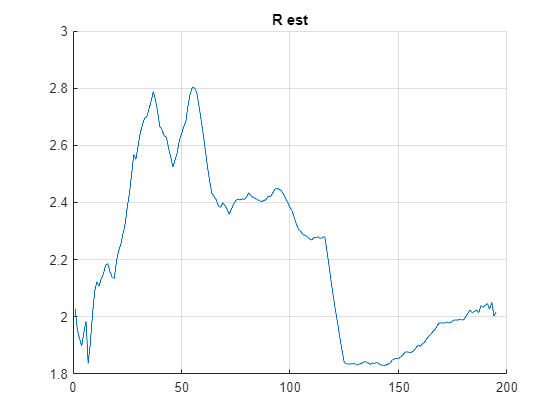


figure;
hold on
plot(R(20:data_length))
plot(R_avr)
hold off
title("R est")
xlim("auto")
ylim("auto")
grid on

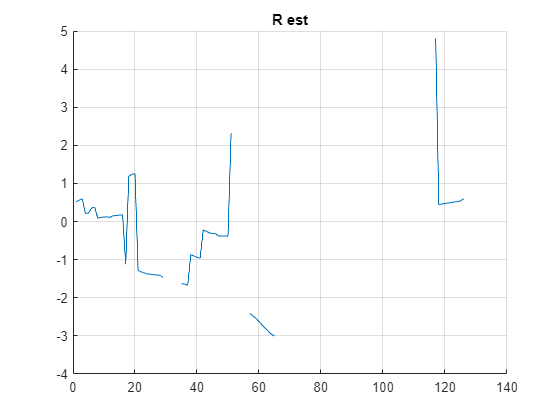

I_est = V/R_avr;

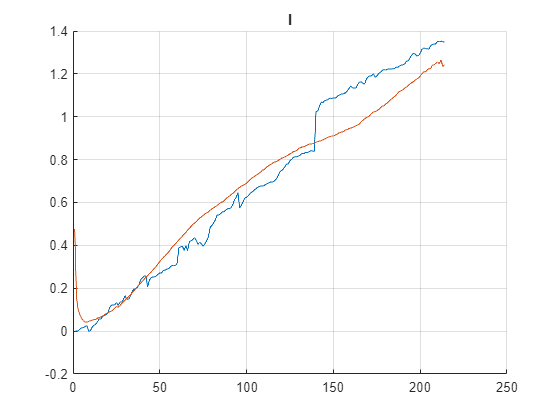


figure;
hold on
plot(I_orig)
plot(I_est)
hold off
title("I")
xlim("auto")
ylim("auto")
grid on